%% WHOLE CODE
clear
% user_settings

%----------------------------------------------------------------
% @SET: fish + conditions
%----------------------------------------------------------------
nfish = 12;
cond_codes = [401:404];
% message = 'tren largo - no aleat (intra?)';
message = 'no sharks';

%----------------------------------------------------------------
% @SET: MEASURE (OR LOOP THROUGH ALL MEASURES)
%----------------------------------------------------------------
reject_on= 1;

setting.manual_reject = 1; %
setting.GSmethod_reject = 1;  %
setting.GSabsthres_reject = 1; %
setting.force_include = 0; %

%----------------------------------------------------------------
% LOAD PARAMETERS
%----------------------------------------------------------------
VSDI = TORus ('load', nfish);

TORus_210522_loaded


movie_ref = '_18filt6'; % input movie '_17filt5'
VSDmov = TORus('loadmovie',nfish,movie_ref);

TORusMov_210522_18filt6.mat_loaded


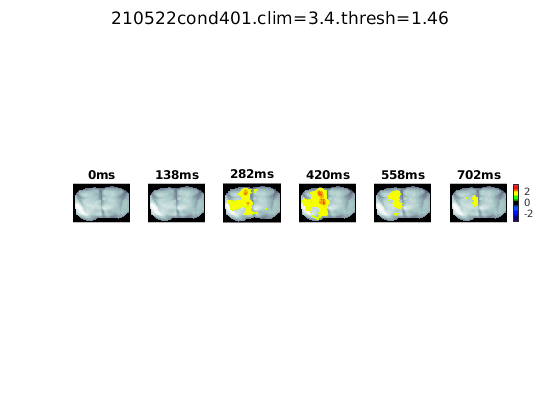

Included trials for condition401:37


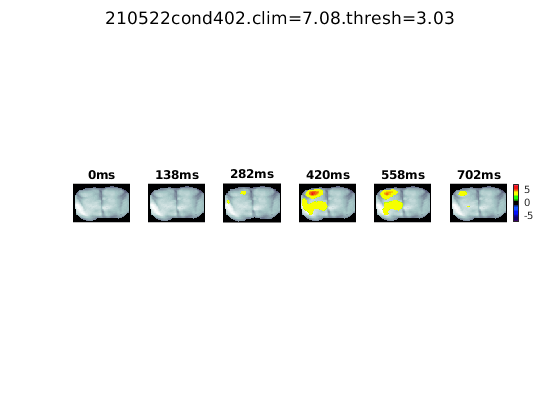

Included trials for condition402:34


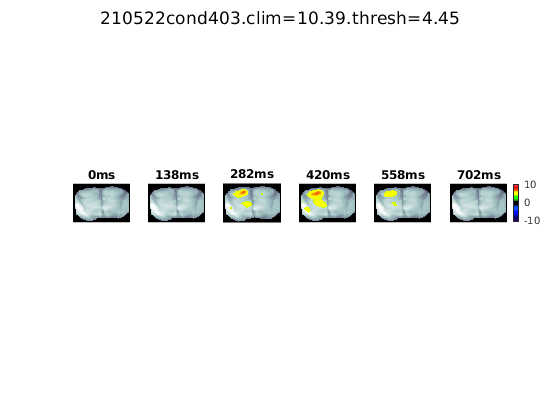

Included trials for condition403:27


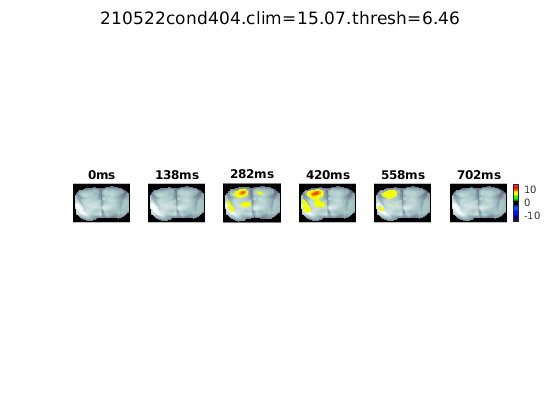

Included trials for condition404:21



%----------------------------------------------------------------
% COMPUTE REJECTION IDX FROM REJECT-OPTIONS
%----------------------------------------------------------------

rejectidx = [];

if setting.manual_reject
    rejectidx = [rejectidx  makeRow(VSDI.reject.manual)];
end

if setting.GSabsthres_reject
    rejectidx = [rejectidx  makeRow(VSDI.reject.GSabs025)];
    
end

if setting.GSmethod_reject
    rejectidx = [rejectidx makeRow(VSDI.reject.GSdeviat2sd)];
end

if setting.force_include
    rejectidx = setdiff(rejectidx, VSDI.reject.forcein);
    
end

rejectidx = sort(unique(rejectidx));


%----------------------------------------------------------------
% PLOT TILES
%----------------------------------------------------------------
for condi = cond_codes
    
    %%
    [sel_trials] = find(VSDI.condition(:,1)==condi);
    sel_trials = setdiff(sel_trials, rejectidx);
    
    
    %to plot single trial
    movie2plot = mean(VSDmov.data(:,:,:,sel_trials),4);
    movie2plot(:,:,end) = VSDI.crop.preview; %clean non-blured background
    % settings
    tileset.start_ms = 0; % time in ms for first tile
    tileset.end_ms = 700;
    %           tileset.clims = [-0.9 0.9];
    maxval = movmedian(movie2plot(:,:,1:end-1),8 ,3); %temporal smooth to get the max value
    maxval = max(maxval(:));
    tileset.clims = [-maxval*1.4 maxval*1.4];
    %     tileset.clims = [-8 8];
    %     tileset.thresh = [-maxval*0.4 maxval*0.4];
    tileset.thresh = [-maxval*0.6 maxval*0.6];
    %     tileset.thresh = [-4.5 4.5];
    
    tileset.nrowcol = [1 6];
    tiles.backgr = VSDI.crop.preview;
    % get info to plot in title
    
    % plot
    %     roi2draw = VSDI.roi.manual_poly([1,2,7,8,13,14]);
    %     plot_tilemovie_custom(movie2plot, VSDI.timebase, tileset, roi2draw);
    plot_tilemovie_custom(movie2plot, VSDI.timebase, tileset);
    
    %         plot_tilemovie_custom(movie2plot, VSDI.timebase, tileset);
    
    %             plot_tilemovie12frames(movie2plot, VSDI.timebase, tileset);
    
    
    titulo = [num2str(VSDI.ref) 'cond' num2str(condi) '.clim=' num2str(round(tileset.clims(2),2)), '.thresh=' num2str(round(tileset.thresh(2),2))];
    sgtitle(titulo)
    
    %     savename= [num2str(VSDI.ref) 'cond' num2str(condi) '_' num2str(numel(sel_trials)) 'trials.jpg']
    disp(['Included trials for condition' num2str(condi) ':' num2str(numel(sel_trials))])
    
end


% newsave = '/home/tamara/Documents/MATLAB/VSDI/TORus/plot/informes_code/03_figure_sketch/def_figs/tiles';
% saveas(gcf, fullfile(newsave,savename) 'jpg')

%----------------------------------------------------------------
% PRINT INCLUDED AND EXCLUDED TRIALS
% ----------------------------------------------------------------

for condi = cond_codes
    
    [sel_trials] = find(VSDI.condition(:,1)==condi);
    local_reject = intersect(sel_trials, rejectidx);%just to display later;
    sel_trials = setdiff(sel_trials, rejectidx);
    
    disp(['Included trials for condition' num2str(condi) ':' ])
    disp(sel_trials)
    disp('%')
    disp(['Rejected trials for condition' num2str(condi) ':'])
    disp(local_reject)
end

Included trials for condition401:


     9
    13
    17
    22
    28
    34
    41
    45
    51
    53
    60
    67
    74
    81
    90
    94
    98
   103
   109
   115
   122
   126
   132
   134
   141
   144
   148
   154
   161
   164
   170
   174
   178
   183
   189
   202
   206


%


Rejected trials for condition401:


    63
    84
   195


Included trials for condition402:


    10
    16
    30
    32
    37
    42
    49
    55
    61
    62
    70
    73
    79
    85
    91
    97
   107
   113
   123
   130
   136
   142
   143
   151
   153
   165
   171
   177
   179
   187
   191
   193
   198
   203


%


Rejected trials for condition402:


    18
    26
    99
   111
   118
   159


Included trials for condition403:


     7
    15
    21
    29
    46
    52
    72
    82
    86
    88
    96
   102
   104
   116
   121
   127
   129
   133
   145
   157
   166
   176
   182
   184
   196
   201
   207


%


Rejected trials for condition403:


    23
    35
    40
    48
    59
    64
    77
   110
   140
   152
   162
   168
   190


Included trials for condition404:


    11
    12
    25
    27
    33
    83
   114
   125
   135
   139
   146
   156
   158
   163
   173
   181
   186
   188
   194
   199
   205


%


Rejected trials for condition404:


    20
    38
    44
    50
    54
    58
    65
    69
    76
    78
    92
    93
   101
   106
   108
   119
   131
   150
   172



%% ----------------------------------------------------------------
%----------------------------------------------------------------
% DISPLAY PARAMETERS
% ----------------------------------------------------------------
%----------------------------------------------------------------
% clearvars -except measure reject_on nfish cond_codes VSDI movies waves ref_wave ...
%     window window_ave noise noise_ave rejectidx roiname1 roiname2 method lat_limit...
%     wavesylim selroi setting
display(['reject' num2str(reject_on)])

reject1



disp('%%%SETTINGS')

%%%SETTINGS


disp(movie_ref)

_18filt6


disp(['clim:' num2str(tileset.clims)])

clim:-15.0731      15.0731


disp(['thresh:' num2str(tileset.thresh)])

thresh:-6.4599      6.4599


%%
% namepdf = [num2str(VSDI.ref) '-block' num2str(cond_codes(1)) '.pdf'];
% % publish('source_code_mixed_pdf.mlx','pdf');
%
% mlxloc = strcat(pwd,'/source_code_mixed_pdf.mlx');
% fileout = strcat(pwd,namepdf);
% matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);
blob()

%% LAST UPDATE: 12/01/22